# Examples 1.5-1.9: Gibbs Reactor under Uncertainty

Note: this script reproduces Examples 1.5 to 1.9 (Sections 1.3 and 1.4) of **Statistics for Chemical Engineers**: the reactor pressure is an RV, and we study how its uncertainty affects conversion and decisions. Victor Z UW-Madison, 2020 gibbs reactor example

clc; clear all; close all hidden;

## Load the pressure data

load data

load ('./Data/gibbs_hightemp.dat')
datahigh=gibbs_hightemp;
load ('./Data/gibbs_lowtemp.dat')
datalow=gibbs_lowtemp;

## Example 1.5: empirical pdf and cdf

Note: the empirical pdf (histogram) and cdf summarize the observed pressures. compare pdf and cdf of pressure

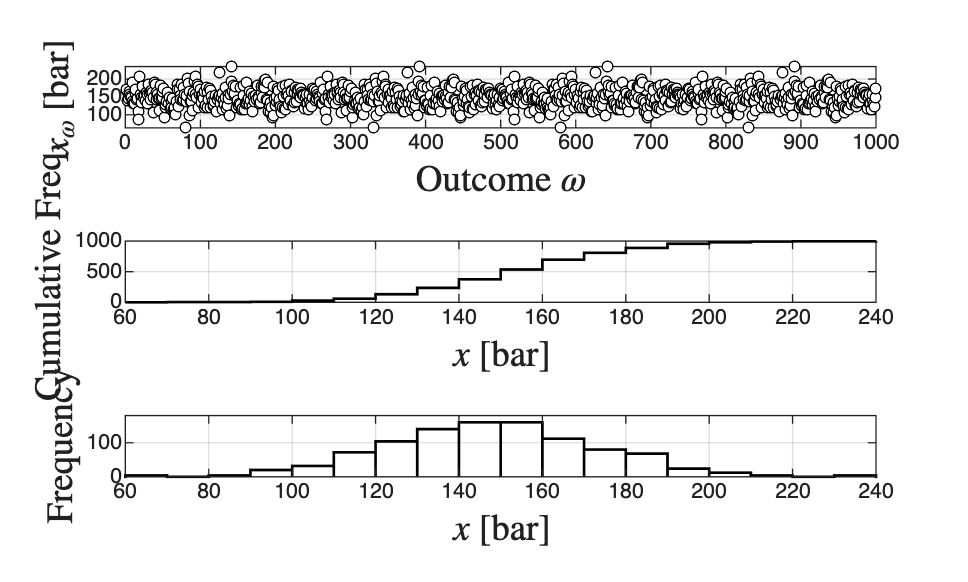

figure(1)
% outcomes
subplot(3,1,1)
plot(datahigh(:,1),'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('Outcome $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$ [bar]','Interpreter','latex','FontSize',14)
grid on

% compute and plot empirical pdf
dx=10;
lb=0;
ub=0;
t=60:dx:240;
x=datahigh(:,1);
N=length(x);

% compute using indicator
for i=1:length(t) 
    f(i)=0;
    lb(i)=t(i);
    ub(i)=t(i)+dx;
    for j=1:N
        f(i)=f(i)+(x(j)<ub(i) && x(j)>=lb(i));
    end
end

% can also automatically visualize empirical pdf using histogram
subplot(3,1,3)
histogram(datahigh(:,1),'BinWidth',10,'Normalization','count','EdgeColor','black','FaceColor','none','LineWidth',1)
xlabel('$x$ [bar]','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Frequency}$','Interpreter','latex','FontSize',14)
axis([60 240 0 180])
grid on

% compute and plot empirical cdf 
t=60:dx:240;

for i=1:length(t) 
    F(i)=0;
    for j=1:length(x)
        F(i)=F(i)+(x(j)<=t(i));
    end
end
subplot(3,1,2)
stairs(t,F,'LineWidth',1,'Color','black')
xlabel('$x$ [bar]','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Cumulative Freq.}$','Interpreter','latex','FontSize',14)
title('')
grid on
print -depsc ch1_gibbs_press_pdf_cdf.eps

## Example 1.5: Gaussian model

Note: the Gaussian model (mean of about 148 bar, SD of about 25 bar) matches the empirical pdf and cdf well, so the pressure behaves as a Gaussian RV. get hyperparameters for Gaussian from data and compare empirical and theoretical pdf/cdf

param = fitdist(datahigh(:,1),'normal')

param =   NormalDistribution

  Normal distribution
       mu = 147.855   [146.286, 149.425]
    sigma = 25.2871   [24.2253, 26.4469]


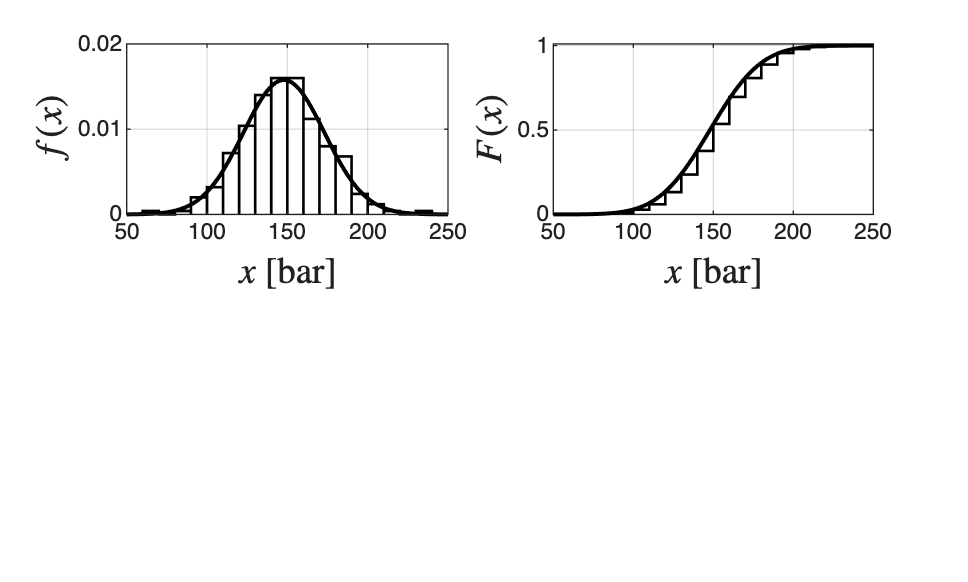

x=linspace(50,250);

figure(2)
subplot(2,2,1)
histogram(datahigh(:,1),'BinWidth',10,'Normalization','pdf','EdgeColor','black','FaceColor','none','LineWidth',1)
hold on
plot(x,normpdf(x,param.mu,param.sigma),'black','LineWidth',1.5)
xlabel('$x$ [bar]','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
grid on
axis([50 250 0 0.02])

subplot(2,2,2)
stairs(t,F/N,'LineWidth',1,'Color','black')
hold on
plot(x,normcdf(x,param.mu,param.sigma),'black','LineWidth',1.5)
grid on
xlabel('$x$ [bar]','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
title('')
axis([50 250 0 1.01])
print -depsc ch1_gibbs_press_pdf_cdf_fit.eps

## Example 1.6: convergence of the estimates

Note: the empirical mean and SD vary a lot for small samples (S below 100) and settle at the theoretical values as S grows. show convergence of empirical approximations as increasing S

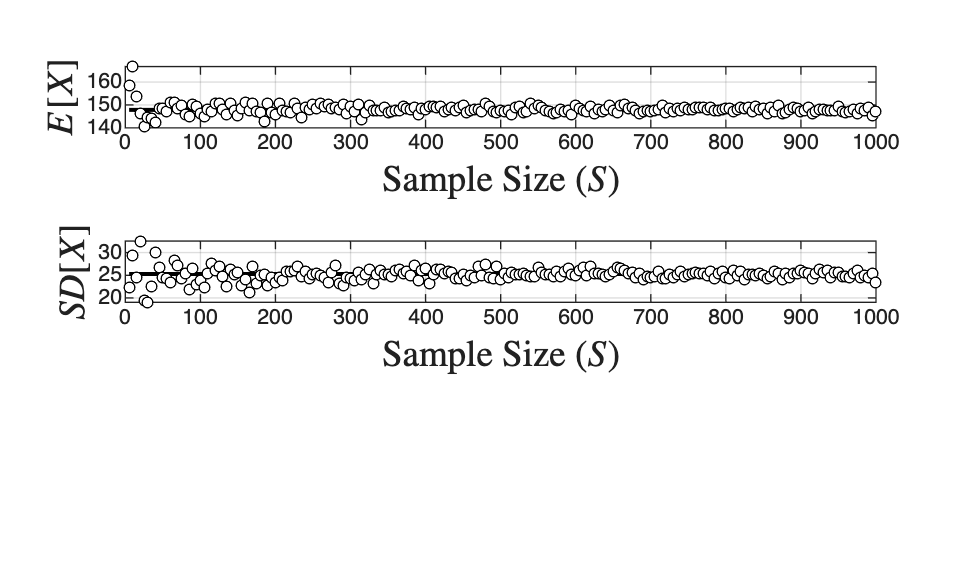

figure(3)
dataP=datahigh(:,1);
Sv=5:5:1000;
rng(1); % For reproducibility 
for j=1:length(Sv)
y = datasample(dataP,Sv(j));
e(j) = mean(y);
v(j) = sqrt(var(y));
end
et=linspace(param.mu,param.mu,length(Sv));
vt=linspace(param.sigma,param.sigma,length(Sv));

subplot(3,1,1)
plot(Sv,et,'black-','LineWidth',1.5)
hold on
plot(Sv,e,'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('Sample Size ($S$)','Interpreter','latex','FontSize',14)
ylabel('$E[X]$','Interpreter','latex','FontSize',14)
grid on
subplot(3,1,2)
plot(Sv,vt,'black-','LineWidth',1.5)
hold on
plot(Sv,v,'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('Sample Size ($S$)','Interpreter','latex','FontSize',14)
ylabel('$SD[X]$','Interpreter','latex','FontSize',14)
grid on
print -depsc ch1_gibbs_press_exp_var.eps


% compute sample moments 
m1=moment(dataP,1)

m1 =      0

m2=moment(dataP,2)

m2 =    6.3880e+02

m3=moment(dataP,3)

m3 =    1.5396e+03

m4=moment(dataP,4)

m4 =    1.3658e+06

sk=skewness(dataP)

sk =    9.5360e-02

ku=kurtosis(dataP)

ku =    3.3469e+00

## Example 1.7: quantiles

Note: the quantile function is the flipped cdf; the median is about 148 bar, equal to the mean for a Gaussian. compute empirical quantile function

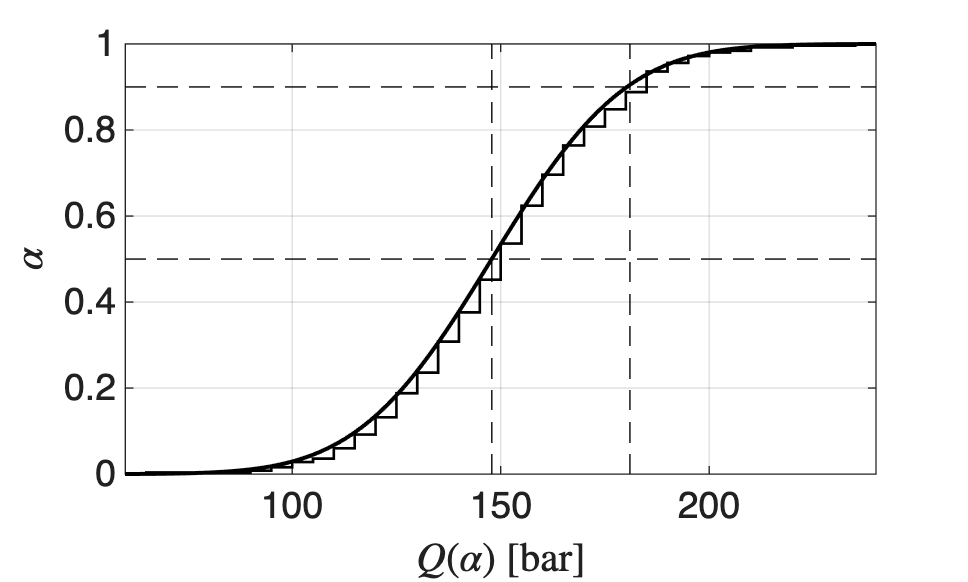

t=60:5:240;
x=datahigh(:,1);
N=length(x);
for i=1:length(t)
    F(i)=0;
    for j=1:length(x)
        F(i)=F(i)+(x(j)<=t(i))*(1/N);
    end
end

figure(4)
yy1=linspace(0.5,0.5,100);
xx1=linspace(quantile(dataP,0.5),quantile(dataP,0.5));
yy2=linspace(0.9,0.9,100);
xx2=linspace(quantile(dataP,0.9),quantile(dataP,0.9));
xx=linspace(60,240);
yy=linspace(0,1);
stairs(t,F,'LineWidth',1,'Color','black')
hold on
x=linspace(50,250);
plot(x,normcdf(x,param.mu,param.sigma),'black','LineWidth',1.5)
axis([60 240 0 1])
plot(xx,yy1,'black--')
hold on
plot(xx1,yy,'black--')
hold on
plot(xx,yy2,'black--')
hold on
plot(xx2,yy,'black--')
grid on
xlabel('$Q(\alpha)$ [bar]','Interpreter','latex','FontSize',16)
ylabel('$\alpha$','Interpreter','latex','FontSize',16)
set(gca,'FontSize',14)
title('')
print -depsc ch1_gibbs_press_quantile.eps

## Example 1.8: uncertainty propagation

Note: the pressure is Gaussian, but the conversion is not (its pdf has two peaks), because the reactor is strongly nonlinear. compare pressure and conversion pdfs at high temperature

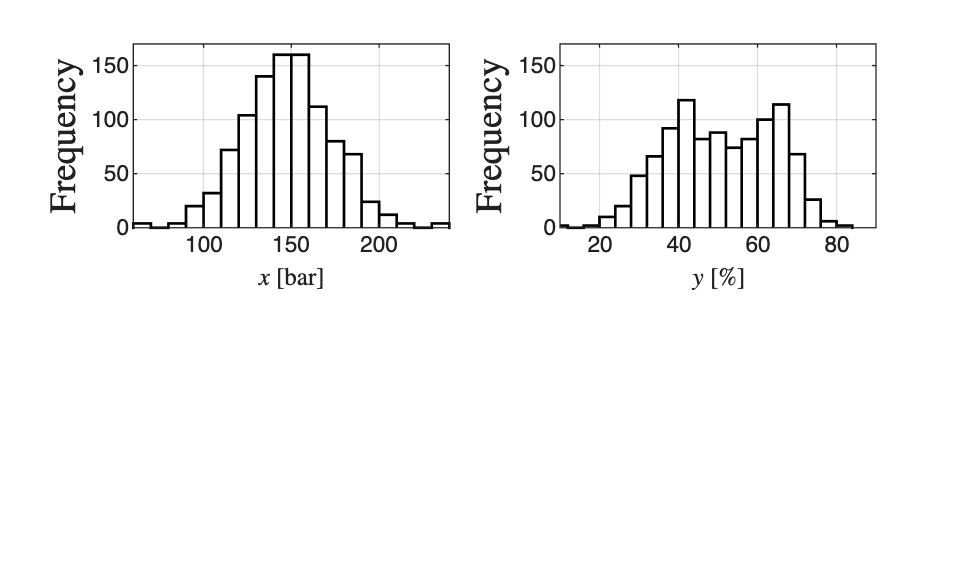

figure(5)
subplot(2,2,1)
histogram(datahigh(:,1),'BinWidth',10,'Normalization','count','EdgeColor','black','FaceColor','none','LineWidth',1)
xlabel('$x$ [bar]','Interpreter','latex')
ylabel('$\textrm{Frequency}$','Interpreter','latex','FontSize',14)
grid on
axis([60 240 0 170])

subplot(2,2,2)
histogram(100*datahigh(:,2),'BinWidth',4,'Normalization','count','EdgeColor','black','FaceColor','none','LineWidth',1)
xlabel('$y$ [\%]','Interpreter','latex')
ylabel('$\textrm{Frequency}$','Interpreter','latex','FontSize',14)
grid on
axis([10 90 0 170])

print -depsc ch1_gibbs_press_extent.eps

## Example 1.9: decision-making under uncertainty

Note: compare the conversion at low (583 K) and high temperature. compare conversion at low and high temperature

figure(6)
subplot(1,2,1)
histogram(100*datahigh(:,2),'BinWidth',4,'Normalization','count','EdgeColor','black','FaceColor','white','LineWidth',1)
hold on
histogram(100*datalow(:,2),'BinWidth',4,'Normalization','count','EdgeColor','black','FaceColor','black','LineWidth',1)
hold on
xlabel('$y$ [\%]','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Frequency}$','Interpreter','latex','FontSize',14)
grid on
legend('High','Low','Location','northwest')

subplot(1,2,2)
t=10:5:100;
F=[];
x=100*datahigh(:,2);
N=length(x);
for i=1:length(t)
    F(i)=0;
    for j=1:length(x)
        F(i)=F(i)+(x(j)<=t(i))*(1/N);
    end
end

stairs(t,F,'LineWidth',1,'Color','black','LineStyle','--')
hold on

t=10:5:100;
x=100*datalow(:,2);
F=[]

F =
     []


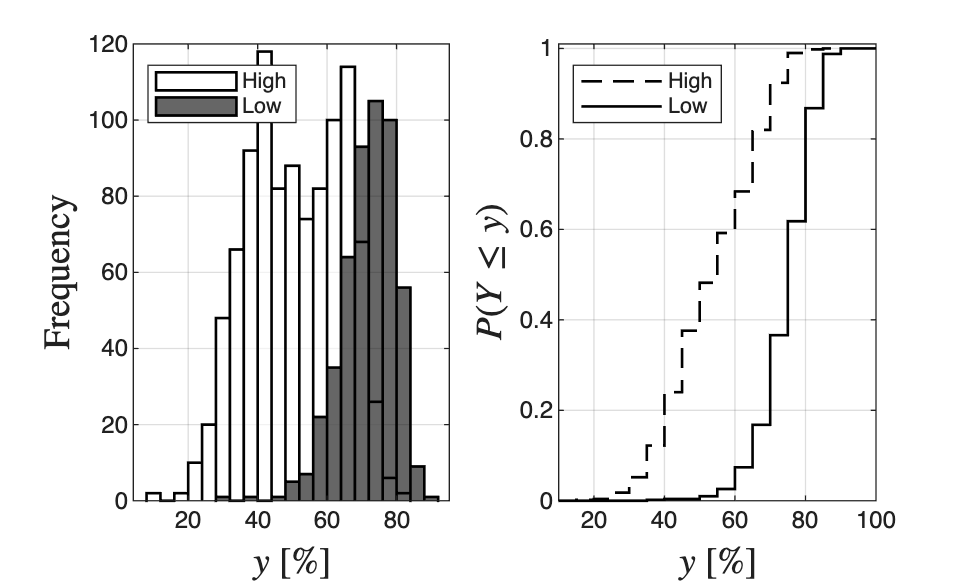

N=length(x);
for i=1:length(t)
    F(i)=0;
    for j=1:length(x)
        F(i)=F(i)+(x(j)<=t(i))*(1/N);
    end
end

stairs(t,F,'LineWidth',1,'Color','black','LineStyle','-')
grid on
axis([10 100, 0 1.01])
title('')
xlabel('$y$ [\%]','Interpreter','latex','FontSize',14)
ylabel('${P}(Y\leq y)$','Interpreter','latex','FontSize',14)
title('')
legend('High','Low','Location','northwest')

print -depsc ch1_gibbs_extent_temp.eps

## Example 1.9: coefficients of variation

Note: the coefficient of variation (SD/mean) measures relative uncertainty. compute coefficients of variation

SD1=std(datahigh(:,2))

SD1 =    1.3329e-01

E1=mean(datahigh(:,2))

E1 =    5.0936e-01

CV1=SD1/E1

CV1 =    2.6169e-01


SD2=std(datalow(:,2))

SD2 =    7.7370e-02

E2=mean(datalow(:,2))

E2 =    7.1893e-01

CV2=SD2/E2

CV2 =    1.0762e-01

## Note

As in the book, operating at low temperature both increases the mean conversion and reduces its uncertainty. In other problems the choice is less obvious: an action may increase the mean but also the uncertainty.